# Probability of detection

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
SR = 48000;                            % 48 KHz Smapling Rate
f0 = 13e+3;                            % 20 KHz
f1 = 10e+3;                            % 10 KHz
f2 = 4e+3;                             % 10 KHz
duration = (127/SR);                   % ~ 2.6 ms 
t = 0:1/SR:duration;                   % Time Vector

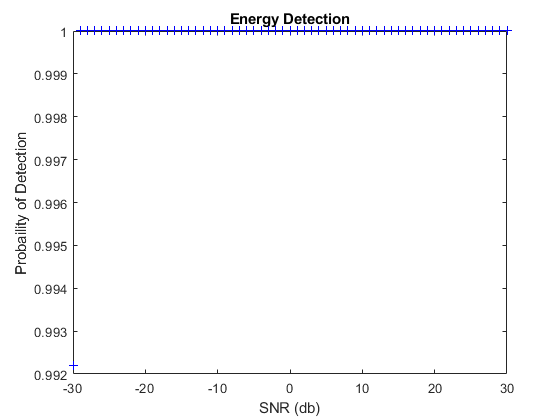

sinusPulse = Am*sin(2*pi*f0*t); 
mySNR = -30:1:30;           % SNR buffer
threshold = 150;
snrValues(sinusPulse,mySNR,threshold)

function snrValues(yourSignal,snr,threshold) 
    for i = 1:length(snr)
        yourSignal = awgn(yourSignal,snr(i));
        find_PD_PFa_ED(yourSignal,threshold);        
        load Pd_Pfa_ED.mat Pd_ED      
        plot(snr(i),Pd_ED,'b+');
        hold on
        title('Energy Detection')
        xlabel('SNR (db)')
        ylabel('Probaility of Detection')
    end
    hold off
end

function find_PD_PFa_ED(yourSignal,threshold)
    Pd_buff(100)=0;
    Pfa_buff(100)=0;
    for j = 1:100
        highValue = 0;
        lowValue = 0;
        a = 0;
        for i = 1:length(yourSignal)
            a = a + abs(yourSignal(i)).^2;
            if a > threshold
                highValue = highValue + 1;
            else
                lowValue = lowValue + 1;
            end
        end
        Pd_buff(j) = highValue/length(yourSignal);
        Pfa_buff(j) = lowValue/length(yourSignal);
    end
    Pd_ED = sum(Pd_buff)/100;
    Pfa_ED = sum(Pfa_buff)/100;
    save Pd_Pfa_ED.mat a Pd_ED Pfa_ED
end